%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       ASSIGNMENT 03       %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc
clear
close all

## 1a) Experimental FRF

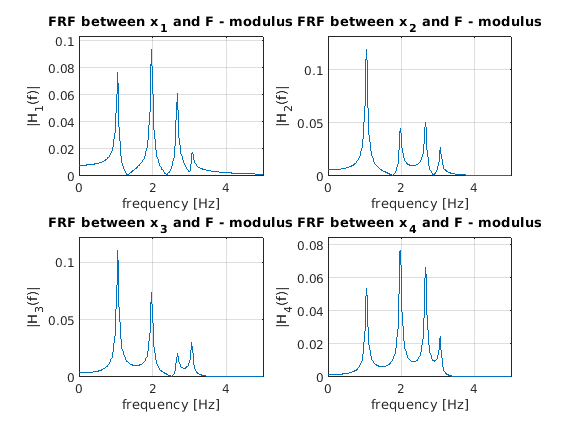

% Importing experimental data
st = load("Data.mat");

t  = st.Data(:,1)';
F  = st.Data(:,2)';
x1 = st.Data(:,3)';
x2 = st.Data(:,4)';
x3 = st.Data(:,5)';
x4 = st.Data(:,6)';

% FFT
fft_F  = fft(F);
fft_x1 = fft(x1);
fft_x2 = fft(x2);
fft_x3 = fft(x3);
fft_x4 = fft(x4);

% FRF
H1 =  fft_x1./fft_F;
H2 =  fft_x2./fft_F;
H3 =  fft_x3./fft_F;
H4 =  fft_x4./fft_F;

% Considering half spectrum (till Nyquist frequency)
H1 = H1(1:round(length(H1)/2));
H2 = H2(1:round(length(H2)/2));
H3 = H3(1:round(length(H3)/2));
H4 = H4(1:round(length(H4)/2));
H  = [H1; H2; H3; H4];

T_s = t(5) - t(4);
f_s = 1/T_s;
f_max = 5;
f = linspace(0,f_s/2,length(H1));

% Plots

figure('Name', 'Experimental FRFs'' modulus');

subplot(2,2,1)
plot(f,abs(H1));
axis([0, f_max, 0, max(abs(H1))*1.1]);
title('FRF between x_1 and F - modulus');
xlabel('frequency [Hz]'); ylabel('|H_1(f)|');
grid on

subplot(2,2,2)
plot(f,abs(H2));
axis([0, f_max, 0, max(abs(H2))*1.1]);
title('FRF between x_2 and F - modulus');
xlabel('frequency [Hz]'); ylabel('|H_2(f)|');
grid on

subplot(2,2,3)
plot(f,abs(H3));
axis([0, f_max, 0, max(abs(H3))*1.1]);
title('FRF between x_3 and F - modulus');
xlabel('frequency [Hz]'); ylabel('|H_3(f)|');
grid on

subplot(2,2,4)
plot(f,abs(H4));
axis([0, f_max, 0, max(abs(H4))*1.1]);
title('FRF between x_4 and F - modulus');
xlabel('frequency [Hz]'); ylabel('|H_4(f)|');
grid on

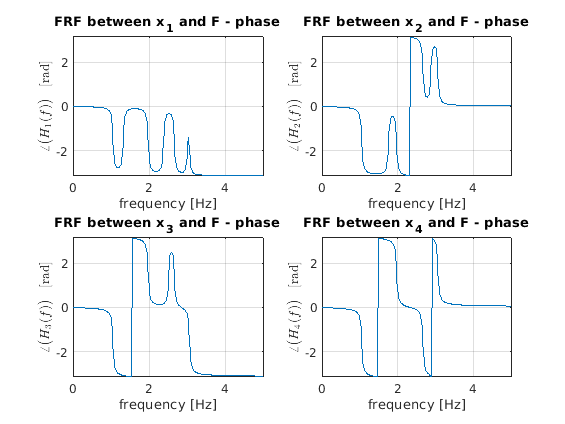



figure('Name', 'Experimental FRFs'' phase');

subplot(2,2,1)
plot(f,angle(H1));
axis([0, f_max, -pi, pi]);
title('FRF between x_1 and F - phase');
xlabel('frequency [Hz]'); ylabel('$ \angle\bigl(H_1(f)\bigr) $ \, [rad]','Interpreter','LaTeX');
grid on

subplot(2,2,2)
plot(f,angle(H2));
axis([0, f_max, -pi, pi]);
title('FRF between x_2 and F - phase');
xlabel('frequency [Hz]'); ylabel('$ \angle\bigl(H_2(f)\bigr) $ \, [rad]','Interpreter','LaTeX');
grid on

subplot(2,2,3)
plot(f,angle(H3));
axis([0, f_max, -pi, pi]);
title('FRF between x_3 and F - phase');
xlabel('frequency [Hz]'); ylabel('$ \angle\bigl(H_3(f)\bigr) $ \, [rad]','Interpreter','LaTeX');
grid on

subplot(2,2,4)
plot(f,angle(H4));
axis([0, f_max, -pi, pi]);
title('FRF between x_4 and F - phase');
xlabel('frequency [Hz]'); ylabel('$ \angle\bigl(H_4(f)\bigr) $ \, [rad]','Interpreter','LaTeX');
grid on

## 1b) Finding natural frequencies, damping ratios and modeshapes with simplified methods

% Finding peaks and their indices
[peaks_H1, indices_H1] = findpeaks(abs(H1));
[peaks_H2, indices_H2] = findpeaks(abs(H2));
[peaks_H3, indices_H3] = findpeaks(abs(H3));
[peaks_H4, indices_H4] = findpeaks(abs(H4));

% Retaining only peaks at least 1 order of magnitude lower than maximum
% peak
indices_H1(peaks_H1 < max(peaks_H1)*1e-1) = [];
peaks_H1(peaks_H1 < max(peaks_H1)*1e-1) = [];
indices_H2(peaks_H2 < max(peaks_H2)*1e-1) = [];
peaks_H2(peaks_H2 < max(peaks_H2)*1e-1) = [];
indices_H3(peaks_H3 < max(peaks_H3)*1e-1) = [];
peaks_H3(peaks_H3 < max(peaks_H3)*1e-1) = [];
indices_H4(peaks_H4 < max(peaks_H4)*1e-1) = [];
peaks_H4(peaks_H4 < max(peaks_H4)*1e-1) = [];

% Each row correspond to single mode
peaks_H   = [peaks_H1; peaks_H2; peaks_H3; peaks_H4];
indices_H = [indices_H1; indices_H2; indices_H3; indices_H4];

% Natural frequencies
f_nat = [f(indices_H1); f(indices_H2); f(indices_H3); f(indices_H4);];

% Applying the Half Power Bandwidth method, we estimated the  factor having the 
% two frequencies w1, w2 in which the FRF halves the power

% The half power approach for estimating damping is based
% on finding the bandwidth for each mode

% Custom function to get row and col length
rows = @(x) size(x,1); 
cols = @(x) size(x,2);

% Init csi matrix
csi = zeros(rows(peaks_H), cols(peaks_H))

csi =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



for x = 1:rows(csi)
    for y = 1:cols(csi)
        thdrs_mag = peaks_H(x,y).*0.5.*sqrt(2);
        i         = indices_H(x,y);
        w0        = f(i);
        w1        = peaks_H(x,y);
        w2        = w1;
        % Search w1
        while (w1 > thdrs_mag)
            %   Looking for index before w0
            i = i - 1;
            w1 = abs(H(x,i));
        end
        w1 = f(i + 1);
        
        % Reset index 
        i  = indices_H(x,y);
        
        % Search w2
        while (w2 > thdrs_mag)
            %   Looking for index after w0
            i = i + 1;
            w2 = abs(H(x,i));
        end
        w2 = f(i - 1);
        
%       Calc csi
        csi(x,y) = (pow2(w2) - pow2(w1))./4*pow2(w0);
    end
end

